# Test Inverse Design Algorithm

Main file to test out the inverse design algorithm for optomechanical crystals. Creates, tests, and optimizes a loss function from `lossFunction.m`. Then compares the optimized geometry to the goal bandgap.

%% Clear before running
clear all

mech = StudyType.Mechanical;
opt = StudyType.Optical;

## Load COMSOL Model

import com.comsol.model.*
import com.comsol.model.util.*

if numel(mphtags) == 1
    model = mphload('Model')
else
    model = mphopen('mphFiles/Bands_SYM.mph', 'Model')
end


model =

COMSOL Model Object
Name: Bands_SYM.mph
Tag: Model
Identifier: root



## Set General Parameters

%% Parameters
h = 530e-9;     % Beam vertical/depth (z-direction) [m]
w = 560e-9;     % Beam width (y-direction) [m]
a = 591e-9;     % Default lattice constant [nm], prefactors below.
a_factor = 0.9; % additional prefactor for default a. 

% Simulation parameters
n_opt = 3;              % number of optical modes/bands to find
dk_opt = 0.2;           % k-point spacing
l_opt = 0.75 * 1550e-9; % optical wavelength to search around
a_nom = a_factor * a;   % nominal unit cell lattice constant

% Set study type
study = opt;

## Set Desired Outputs

bg_cen = 2.085809266547018e+14; % Center of bandgap to aim for
bg = 4.791579117048141e+13;     % Width of bandgap to aim for

## Set Model Initial Parameters

% nominal unit cell geometry
% fill factor (ff) in units of a (unit cell lattice constant)
ff_0 = 0.20;    %(radius of nominal circle)

% Set geom parameters for COMSOL
h_nom_0 = ff_0 * a_nom * 2; % diam of nominal ellipse in [nm] 

## Test loss function

tic
[SSR, values] = lossFunction(...
    model, study, 'bg_cen', bg_cen, 'bg', bg, ...
    h=h, w=w, a=a_nom, dk=dk_opt, n=n_opt, l=l_opt, hx=h_nom_0, hy=h_nom_0, showProgress=true ...
)

SSR = 6.8055e-30

values = 	1.0e+14 *

    2.0858    0.4792


toc

Elapsed time is 22.728859 seconds.


## Run Optimization to find best geometry

 
 Iteration   Func-count     min f(x)         Procedure
     0            1         0.239558         
     1            2         0.194738         initial simplex
     2            4         0.115338         expand
     3            6          0.01449         expand
     4            8      0.000377955         reflect
     5           10      5.30281e-05         contract inside
     6           12      8.98884e-09         contract inside


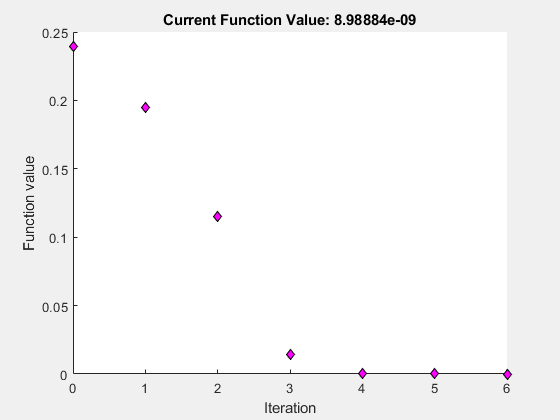

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



x = 3.1914e-07

fval = 8.9888e-09

exitflag = 1

output = struct with fields:
    iterations: 6
     funcCount: 12
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


tic
% Create loss function in the format needed by fminsearch
optim = @(h_nom) lossFunction(...
    model, study, 'bg_cen', bg_cen, 'bg', bg, ...
    h=h, w=w, a=a_nom, dk=dk_opt, n=n_opt, l=l_opt, hx=h_nom, hy=h_nom ...
);
% Run optimization with results in real-time
options = optimset('Display', 'iter', 'PlotFcns', @optimplotfval);
[x, fval, exitflag, output] = fminsearch(optim, h_nom_0, options)

toc

Elapsed time is 306.801709 seconds.


## Calculate optimized geometry

tic
optim_ff = x / a_nom / 2;
[optim_SSR, optim_values] = lossFunction(...
    model, study, 'bg_cen', bg_cen, 'bg', bg, ...
    h=h, w=w, a=a_nom, dk=dk_opt, n=n_opt, l=l_opt, hx=x, hy=x ...
);

fprintf('The optimized fill factor is: %f\nBandgap Center: %f THz\nBandgap Width: %f THz', ...
    optim_ff, optim_values(1) / 1e12, optim_values(2) / 1e12)

The optimized fill factor is: 0.300000
Bandgap Center: 208.574318 THz
Bandgap Width: 47.920073 THz

toc

Elapsed time is 23.038298 seconds.
